**Load paths**

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


## **How pressure changes during large leakages and fire-fighting?**

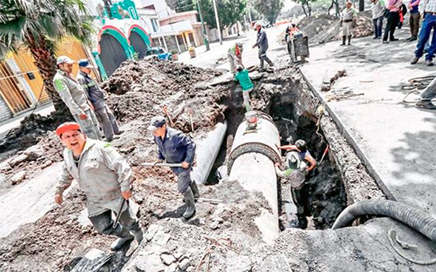          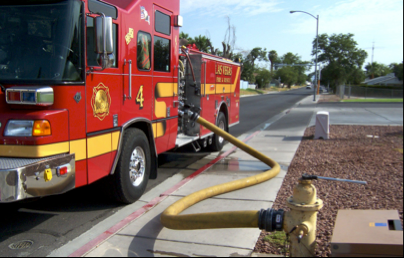

When flow is increased within the network, e.g., due to fire-fighting, the pressure changes near that location. Investigate this change, at node '32'.

G = epanet('Net1.inp');

EPANET version {20200} loaded (EMT version {v2.2.4 - Last Update: 08/12/2022}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.


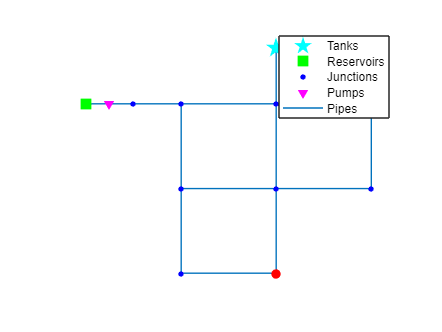

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


nodeID = {'32'};
figure
G.plot('highlightnode', nodeID)

**During fire-fighting, the base demand may increase up to x5. Will there be sufficient pressure?**

idx = G.getNodeIndex(nodeID)

idx =      9


bd = G.getNodeBaseDemands{1}(idx)

bd =    100



demand_multi = 8 % demand multiplicator

demand_multi =      8



d32 = bd *(1:demand_multi) % create the different demands

d32 =    100   200   300   400   500   600   700   800



p32min = zeros(1,length(d32)); % initialize variable
for i = 1:length(d32)
    G.setNodeBaseDemands(idx,d32(i));
    p32 = G.getComputedHydraulicTimeSeries.Pressure(:,idx);
    p32min(i) = min(p32);
end

**Plot demand vs pressure**

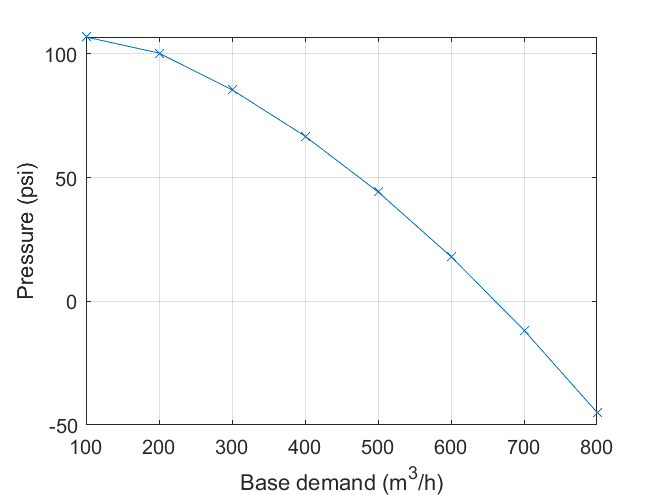

figure
plot(d32, p32min,'x-')
grid on
xlabel('Base demand (m^3/h)')
ylabel('Pressure (psi)')

How about those negative pressures?

## **Pressure Driven Simulations**

When the pressure is low, it should approximate zero. This is not the default mode of operation in EPANET. However, it's easy to set it up:

type = 'PDA';
pmin = 0;
preq = 0.1;
pexp = 0.5;
G.setDemandModel(type, pmin, preq, pexp)

Let's try this again

demand_multi = 10 % demand multiplicator

demand_multi =     10


d32 = bd *(1:demand_multi) % create the different demands

d32 =          100         200         300         400         500         600         700         800         900        1000


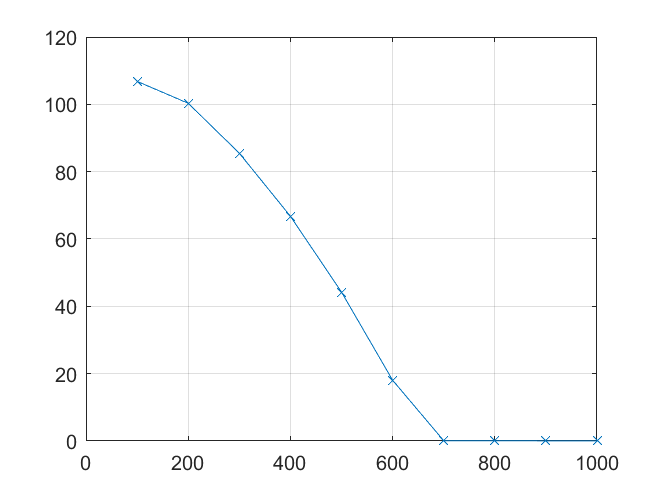


p32min = zeros(1,length(d32)); % initialize variable
for i = 1:length(d32)
    G.setNodeBaseDemands(idx,d32(i));
    p32 = G.getComputedHydraulicTimeSeries.Pressure(:,idx);
    p32min(i) = min(p32);
end

figure
plot(d32, p32min,'x-')
grid on

G.unload

EPANET Class is unloaded


## **Leakage Simulations**

Load network

d = epanet('Hanoi_pat.inp');

EPANET version {20200} loaded (EMT version {v2.2.4 - Last Update: 08/12/2022}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Hanoi_pat.inp"...
Input File "Hanoi_pat.inp" loaded successfully.


d.setTimeSimulationDuration(7*24*60*60)
d.setTimeHydraulicStep(300)

Simulate without leak

sim_leak_free = d.getComputedHydraulicTimeSeries;

Get inflow without leak and create measurements by inserting random noise

res_ind = d.getNodeReservoirIndex;
for i = 1:length(d.getNodeReservoirIndex)
    res_link(i)=find(d.NodesConnectingLinksIndex(:,1)==d.getNodeReservoirIndex(i));
end
Inflow1 = sim_leak_free.Flow(:,res_link); % inflow
eta = rand(length(Inflow1),1)*mean(Inflow1)*0.0001;
y1 = Inflow1.*(1+eta); % measured inflow
figure
plot(y1)
grid on
hold all

Simulate leakage:

leak_node = 10;
leak_emit = 20; % random leak emiter coefficient [2 20]
emit = d.getNodeEmitterCoeff;
emit = zeros(size(emit));
emit(leak_node) = leak_emit; % set emitter coefficient (leakage) value
d.setNodeEmitterCoeff(emit);
sim_leak = d.getComputedHydraulicTimeSeries;

Get inflow with leak and create measurements by inserting random noise

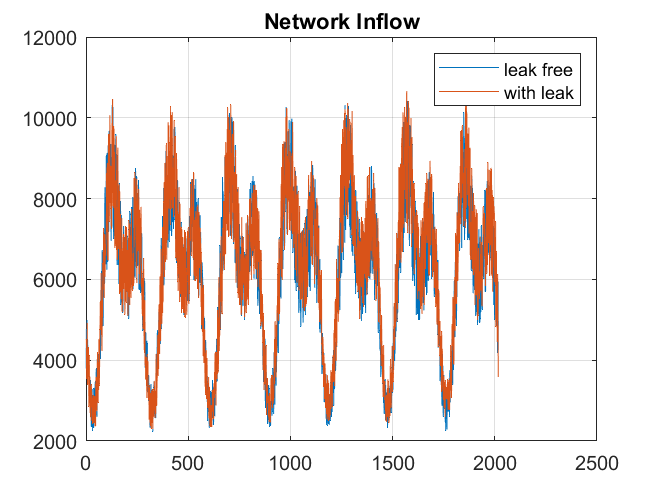

res_ind = d.getNodeReservoirIndex;
for i=1:length(d.getNodeReservoirIndex)
    res_link(i)=find(d.NodesConnectingLinksIndex(:,1)==d.getNodeReservoirIndex(i));
end
Inflow2 = sim_leak.Flow(:,res_link); % inflow
Inflow2(1:3*288)=Inflow1(1:3*288); % change leak start time
eta = rand(length(Inflow2),1)*mean(Inflow1)*0.0001;
y2 = Inflow2.*(1+eta); % measured inflow
plot(y2)
title('Network Inflow')
legend('leak free', 'with leak')

Plot leakage location:

d.plot

ans =   Axes with properties:

             XLim: [2261.7 7714.9]
             YLim: [4038.5 9407.7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


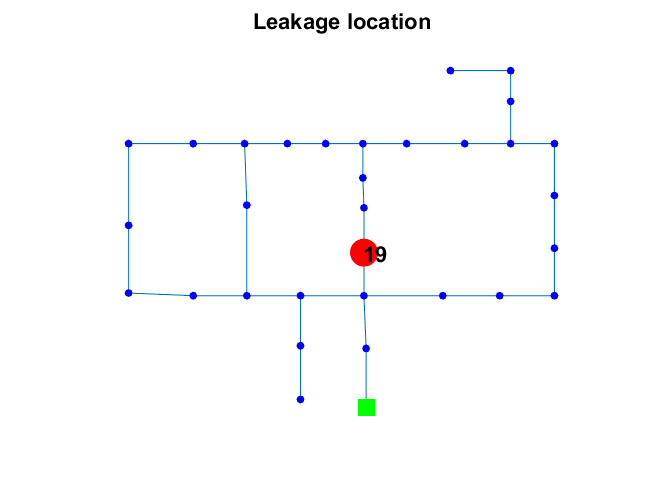

legend('off')
coor=d.getNodeCoordinates;
x=coor{1}(leak_node);y=coor{2}(leak_node);
plot(x,y,'o','LineWidth',2,'MarkerEdgeColor','r','MarkerFaceColor','r','MarkerSize',12)
fontweight='bold';
fontsize=11;
for i=1:length(leak_node)
    text(x(i)-5,y(i),d.getNodeNameID{leak_node(i)},'Color','black','FontWeight',fontweight,'Fontsize',fontsize)
end
title('Leakage location')

## **Leakage Detection**

**Minimum Night Flow Analysis**

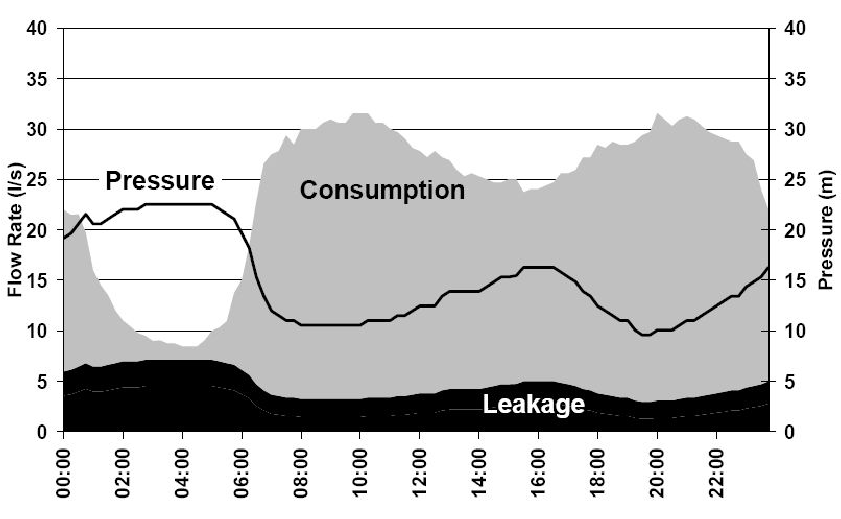

- Basic idea is that each night the uncertainty is low

- Demand is low

- Pressure is high

- Easier to detect leakages

% compute the minimum flow for each day
Y = reshape(y2(2:end),288,7)

Y =        4512.3       4101.9       3971.7       4411.6       4411.5       4402.4       4785.8
       3533.4       4008.2       4733.1       3754.9         4329       4304.2       4113.1
       3773.2       3534.6       4350.8       5166.3       3888.3       3870.1       4970.7
       3871.9       3513.9       4755.1       4319.3       4337.7       4053.1       3873.7
       4922.9       3599.3       3541.3       4309.4       4416.4       5098.2       3984.4
       3394.7       4067.4       3339.2       3262.5       4577.1       4597.3       4156.1
       3423.9       3379.4         3995       4022.9       4348.5         3990       4588.4
       4065.1       3406.9       3146.9       4739.2       4196.6       4174.4         4510
       4023.4       3064.1       4165.1       3651.4       3358.1       4350.5       4148.8
       4106.2       4141.3       3955.8       4391.1       3392.9       3437.5       3219.9


MF = min(Y)

MF =        2362.5       2298.4       2355.3       2463.8       2505.5       2456.4       2590.3


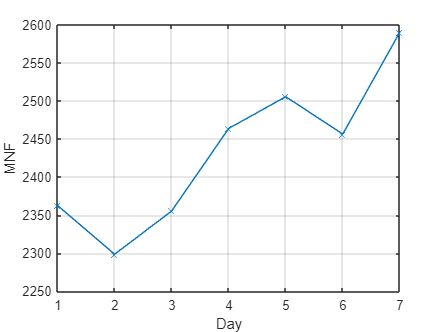

figure 
plot(MF,'-x')
xlabel('Day')
ylabel('MNF')
grid on

%grid on
%line([100,0],[9,9])

**Detecting changes**

- Change detection algorithms

- Limit checking, change in mean

- Cumulative Sum (CUSUM)

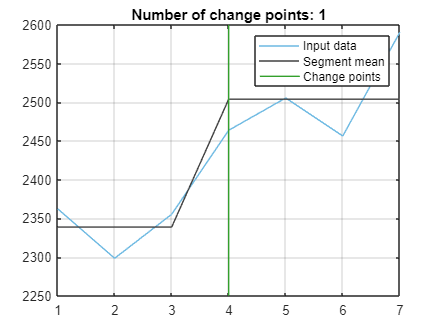


% Find change points
%[changeIndices, segmentMean] = ischange(MF,'Threshold',1);
[changeIndices, segmentMean] = ischange(MF,'MaxNumChanges',1);

% Visualize results
clf
plot(MF,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot segments between change points
plot(segmentMean,'Color',[64 64 64]/255,'DisplayName','Segment mean')
grid on

% Plot change points
x = repelem(find(changeIndices),3);
y3 = repmat([ylim(gca) NaN]',nnz(changeIndices),1);
plot(x,y3,'Color',[51 160 44]/255,'LineWidth',1,'DisplayName','Change points')
title(['Number of change points: ' num2str(nnz(changeIndices))])

hold off
legend

clear segmentMean x y3


Limit checking, the most simple detection algorithm

threshold = 30

threshold =     30


alert = MF-MF(1) > threshold

alert = 1×7 logical array
   0   0   0   1   1   1   1


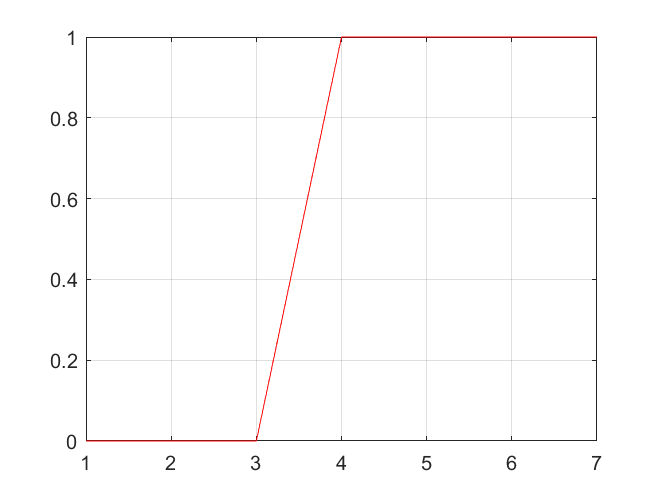


figure
plot(alert, 'r-')
grid on

A different approach would be to take a window of minimum (night) flows, and compare them with the new minimum flow. If it exceeds a precalculated distance, the issue an alert.